# KPM计算电导率


clear;
col_tot = 100;
row_tot = 1;
t = 1;
t_x = t;
t_y = t;
epsilon = 0;
% Magnetic flux, flux quantum as unit
phi = 0;
Temperature = 0;


% H_sparse = get_Nearest_Square_Hopping_Sparse(row_tot, col_tot, t_x, t_y);
H_sparse = Hamiltonian_2D_KPM(col_tot, row_tot, epsilon, phi, t);
x_operator = kron(spdiags((1:col_tot)', 0, col_tot, col_tot), speye(row_tot));
y_operator = kron(speye(col_tot), spdiags((1:row_tot)', 0, row_tot, row_tot));
v_operator_x = 1i * sparse(H_sparse * x_operator - x_operator * H_sparse);
v_operator_y = 1i * sparse(H_sparse * y_operator - y_operator * H_sparse);

tic;

%% KPM计算电导率

N_randvec = 20;
N_moments = 200;
N_points = 2 * N_moments;
% N_points = 400;
[H_tilde, a, b] = KPM_scaleHamiltonian(H_sparse);
e_scaled = KPM_Chebyshev_abscissas(N_points);
energies = e_scaled * a + b;

% 制造[1,0,0...0]向量与kwant对比
% rand_ket = zeros(size(H_tilde,1),1);
% rand_ket(1) = 1;
% Moments_Mat = KPM_Moments_Correlator(H_tilde, 1, N_moments, v_operator_x, v_operator_x, 'gpu', rand_ket);

Moments_Mat = KPM_Moments_Correlator(H_tilde, N_randvec, N_moments, v_operator_x, v_operator_x, 'gpu');

Moments_Kernel = KPM_Kernel_Correction(Moments_Mat, N_moments);


integral = zeros(1, length(energies));

integral_factor = zeros(1, length(energies));


for ii = 1:length(e_scaled)
    Gamma = KPM_Correlator_basis(e_scaled(ii), N_moments);
    integral_factor(ii) = tensorprod(Moments_Kernel, Gamma.','all');
end

for ii = 1:length(energies)
    fermi_distribution = KPM_fermi_distribution(energies, energies(ii), Temperature);
    integrand = (fermi_distribution ./ ((1 - e_scaled.^2).^2)) .* integral_factor;
    integral(ii) = trapz(e_scaled, integrand);
end
toc;

历时 0.153654 秒。


% Original coefficient
% Conductivity_xx = 2 * integral / a^2 / pi^2 ;
% kwant coefficient
Conductivity_xx = (8 / a^2) * integral;
area = 1;
Conductivity_xx = Conductivity_xx / area;





# NEGF计算电导率


% clear;
%%  初始参数定义，能量尺度，采点数，单层格子数，在位能，跃迁能等
% 导线参数
% energy scale

    energyscale = 4;
% sampling points of energy
    N_point = N_points;
% number of unitcell in one layer of central
    Length = 1;
    Width = row_tot;
% number of atoms in one layer of wire
    % N_site = 3;
% onsite energy
    epsilon = 0;
% hopping
    t = 1;
% infinitesimal parameter
    eta = 1e-6;
% 迭代次数
    Iteration = 70;
    layer = 1;
    ave = 1;
    omega = linspace(-energyscale,energyscale,N_point);

    %% 导线哈密顿量
    [H00_wire, V_wire] = Hamiltonian_2D_Real(Length, Width, epsilon, phi, t);
    Iden = eye(Width);
    % Coupling Strength of wire and Lieb lattice 
    Tr = 1;
    % Count the time of the program
    tic;
    %% 计算格林函数与电导率
    % 中心区哈密顿量，以及初始化参数
    H_CC = H00_wire;
    V_CC = V_wire;
    G_00_Right = zeros(Width, Width);
    G_00_Left = zeros(Width, Width);
    Transmission = zeros(1,length(omega));

    % 计算每个频点的透射率
    for ii = 1:length(omega)
        G_00_Right = SurfaceGreenFunction(H00_wire, V_wire, omega(ii), Iteration);
        G_00_Left = SurfaceGreenFunction(H00_wire, V_wire', omega(ii), Iteration);

        Sigma_L = SurfaceGreenFunction_SelfEnergy(G_00_Left, Tr');
        Sigma_R = SurfaceGreenFunction_SelfEnergy(G_00_Right, Tr);
        
        Gamma_L = SurfaceGreenFunction_Broadening(Sigma_L);
        Gamma_R = SurfaceGreenFunction_Broadening(Sigma_R);
        for jj = 1:ave
            G_Centre_Ret = SurfaceGreenFunction_Gcc_1L(H_CC, V_CC, layer, omega(ii), Sigma_L, Sigma_R);
            Transmission(jj,ii) = real(GreenFunction_Transmission(Gamma_L, Gamma_R, G_Centre_Ret));
        end
    end

    toc;

历时 0.376069 秒。


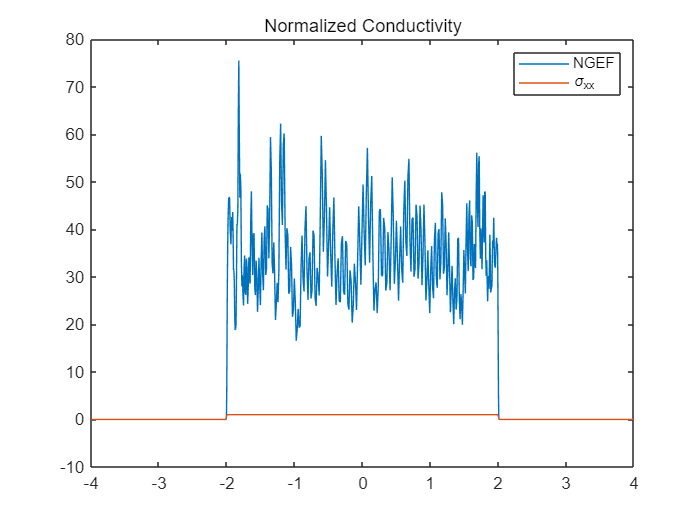

% plot(energies, abs(Conductivity_xx),omega, Transmission);
% title('unnormalized')
plot(energies, real(Conductivity_xx),omega, normalize(Transmission,'range'));
title('Normalized Conductivity')
% hold off
legend({'NGEF','\sigma_{xx}'})





function [H_00, H_01] = Hamiltonian_2D_Real(Length, Width, epsilon, phi, t)
    
    H_00 = sparse(epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1));
    H_01 = sparse(-t * diag(exp(1i * 2*pi* (1:Width) * phi)));

    % H = kron(speye(Length), H_00) + kron(spdiags(ones(Length, 1),1, Length, Length), H_01') + kron(spdiags(ones(Length, 1),-1, Length, Length), H_01);
    

end

function H = Hamiltonian_2D_KPM(Length, Width, epsilon, phi, t)
    
    H_00 = sparse(epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1));
    H_01 = sparse(-t * diag(exp(1i * 2*pi* (1:Width) * phi)));

    H = kron(speye(Length), H_00) + kron(spdiags(ones(Length, 1),1, Length, Length), H_01') + kron(spdiags(ones(Length, 1),-1, Length, Length), H_01);
    

end
